This function has two distinct frequencies. 

f = @(x) 3*cos(5*pi*x) - exp(2i*pi*x);

We set up to use the built-in `fft`. Note how the definition of the nodes has changed. 

n = 10;
N = 2*n+1;
t = 2*(0:N-1)'/N;      % nodes in $[0,2)$
y = f(t);

We perform Fourier analysis using `fft` and then examine the coefficients.

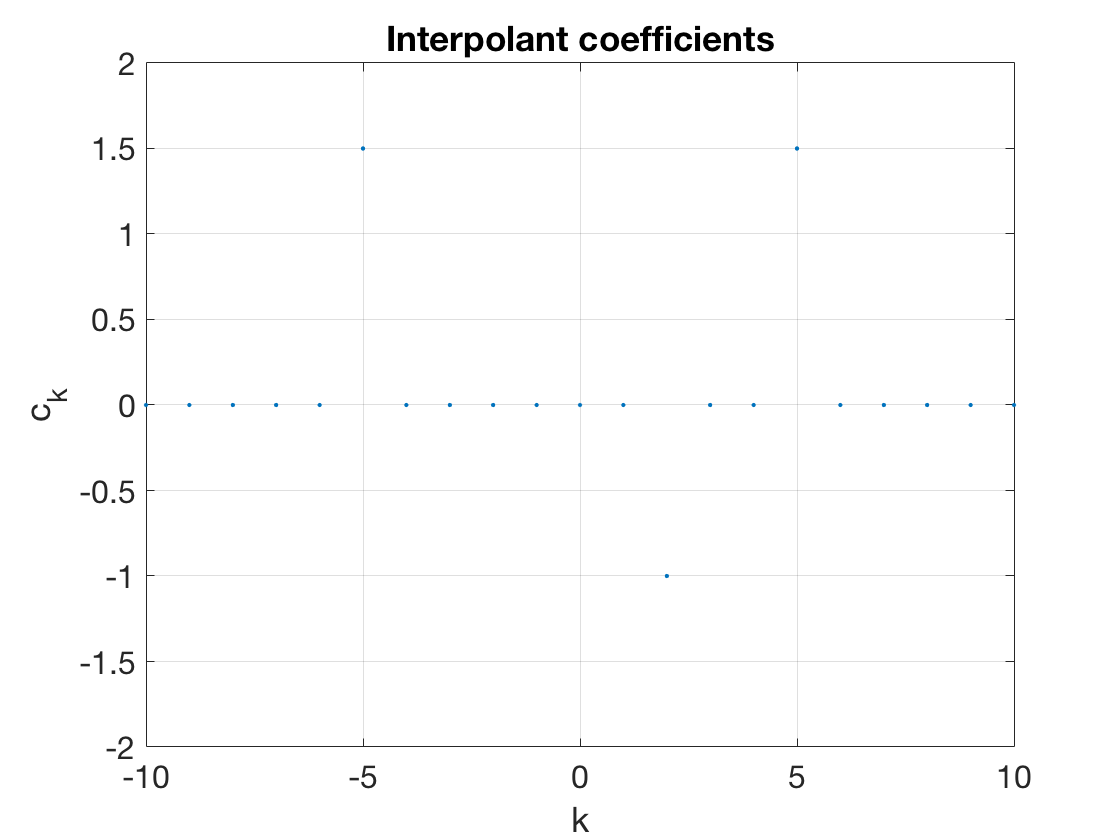

c = fft(y)/N;
k = [0:n -n:-1]';    % frequency ordering for MATLAB
plot(k,real(c),'.')
axis([-n n -2 2]), grid on
xlabel('k'), ylabel('c_k'), title('Interpolant coefficients')   % ignore this line

Note that $1.5 e^{5i\pi x}+1.5 e^{-5i\pi x} = 3 \cos(5\pi x)$ by Euler's formula, so this result is sensible.

Fourier's greatest contribution to mathematics was to point out that every periodic function is just a combination of frequencies---infinitely many of them in general, but truncated for computational use. 

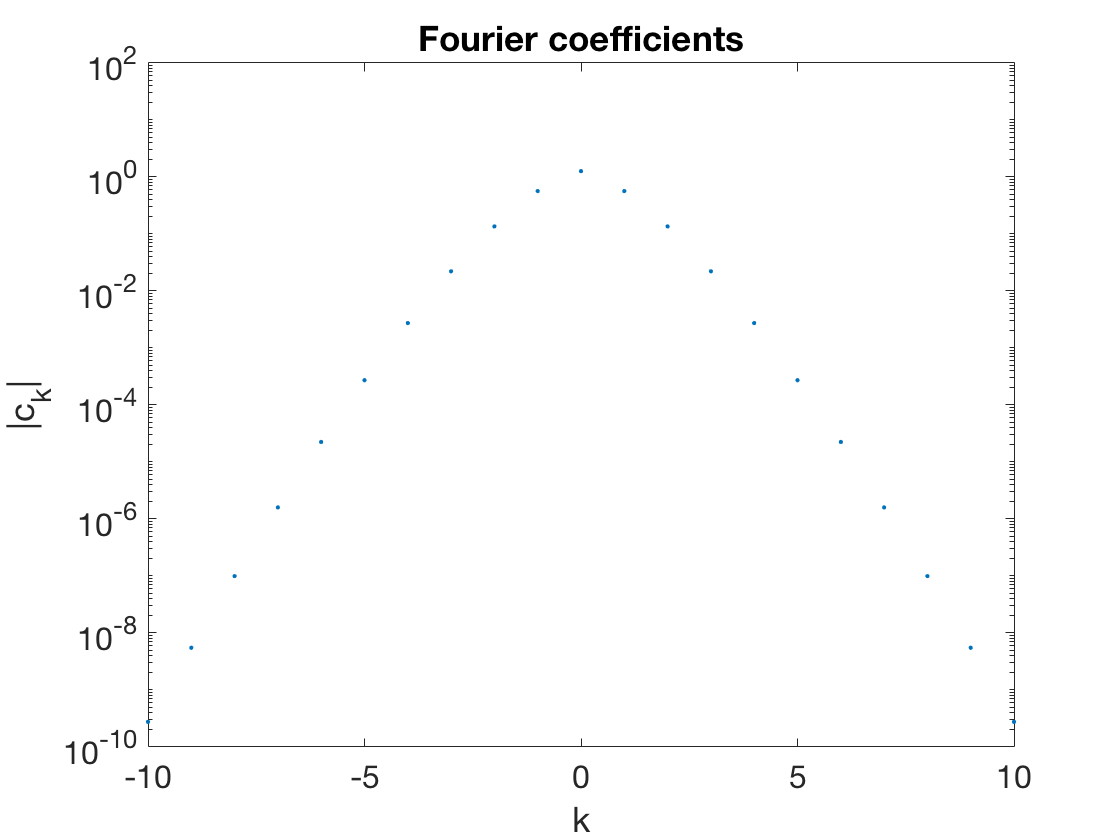

f = @(x) exp( sin(pi*x) );
c = fft(f(t))/N;
semilogy(k,abs(c),'.')
xlabel('k'), ylabel('|c_k|'), title('Fourier coefficients')   % ignore this line

The Fourier coefficients of smooth functions decay exponentially in magnitude as a function of the frequency. This decay rate is directly linked to the convergence of the interpolation error.